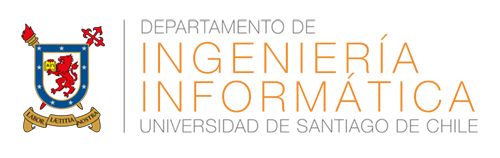

# Tarea N° 4

## PROCESAMIENTO DE SEÑALES E IMÁGENES

Jaime Riquelme Olguin

Profesores:

- Violeta Chang C.

- Alejandro Catalán.

Ayudante: Luis Corral

## Puntos Clave del Proceso

En este proceso de eliminacion de ruido feedback, se consideran los siguientes factores principales:

- Obtener la frecuencia adecuada del ruido feedback, la cual será detectada mediante el algoritmo.

- Utilizar el filtro notch para eliminar especificamente esa frecuencia.

## Fórmula del Filtro Notch a utilizar

El filtro notch fué entregado por el ayudante, el cual utiliza la funcion "fdesign.notch" para eliminar la frecuencia.

### filt = design(fdesign.notch('N,F0,Q', 4, f_noise, 6.5, Fs), 'Systemobject', true);

## Transformada de Fourier

Para poder analizar el espectro de frecuencias de la señal, utilizamos la tranformada de fourier (FFT)

### Y = fft(y)

## Proceso utilizado para eliminar el ruido

- **Lectura del archivo de audio**: Se carga el archivo .wav especificado por el usuario en consola.

- **Analisis espectral**: Se calcula el espectro de frecuencias utilizando la FFT.

- **Detección de la frecuencia del ruido**: Se identifica el pico más alto en el espectro de frecuencias.

- **Aplicación del filtro**: Se aplica el filtro notch a la señal original para eliminar el ruido.

- **Visualización**: Se grafican los espectros de frecuencia antes y después del filtrado.

- **Reproducción de audio**: Se reproduce el audio original y el filtrado para comparación auditiva.

- **Guardado del resultado**: Se guarda el audio filtrado en un nuevo archivo.

## CODIGO

% Solicitamos el nombre del archivo de audio
filename = input('Ingrese el nombre del archivo de audio (incluyendo la extensión .wav): ', 's');

% Leer el archivo de audio
[y, Fs] = audioread(filename);
fprintf('Frecuencia de muestreo: %d Hz\n', Fs);

Frecuencia de muestreo: 48000 Hz



% Calcular el espectro de frecuencias
N = length(y);
f = (0:N-1)*(Fs/N);
Y = fft(y); %aplicamos la tranformada de fourier
Y_abs = abs(Y);

% Encontramos la frecuencia del ruido
[~, index] = max(Y_abs);
f_noise = f(index);
fprintf('Frecuencia de ruido detectada: %.2f Hz\n', f_noise);

Frecuencia de ruido detectada: 1600.08 Hz


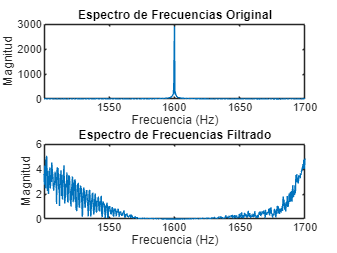


% Utilizamos el filtro notch con la frecuencia encontrada
filt = design(fdesign.notch('N,F0,Q', 4, f_noise, 6.5, Fs), 'Systemobject', true);
y_filtered = filt(y);

% Calculamos el espectro de frecuencias del audio filtrado para mostrarlo
Y_filtered = fft(y_filtered);
Y_filtered_abs = abs(Y_filtered);

% Graficar los espectros de frecuencia
figure;

% Espectro original
subplot(2,1,1);
plot(f, Y_abs);
title('Espectro de Frecuencias Original');
xlabel('Frecuencia (Hz)');
ylabel('Magnitud');
hold on;
hold off;
xlim([max(0, f_noise-100), min(f_noise+100, Fs/2)]);

% Espectro filtrado
subplot(2,1,2);
plot(f, Y_filtered_abs);
title('Espectro de Frecuencias Filtrado');
xlabel('Frecuencia (Hz)');
ylabel('Magnitud');
xlim([max(0, f_noise-100), min(f_noise+100, Fs/2)]);


% Reproducir audios
fprintf('audio original\n');

audio original


sound(y, Fs);
fprintf('audio filtrado\n');

audio filtrado


sound(y_filtered, Fs);

% Guardar el audio filtrado
output_filename = ['filtrado', filename];
audiowrite(output_filename, y_filtered, Fs);
fprintf('Audio filtrado guardado como: %s\n', output_filename);

Audio filtrado guardado como: filtradoaudio8.wav
